[FileName,PathName] = uigetfile('*.jpg','Select the Image');          %%to select the cover image which will overlay the image to be protected
file = fullfile(PathName,FileName);                                         %%command to select the image via computer pop up
disp(['User selected : ', file]);                                           %%disp the selected image

User selected : C:\Users\adity\Desktop\Face Recognition\training_data\0\person1_01.jpg


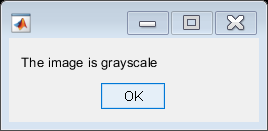

img = imresize(imread(file),[750 750]);                                   %%resize image so that the cover image would always be greater than the image to be protected
img = double(img);                                                      %%make a copy of the cover image
if ndims(img) ~= 3                                                        %%To make sure that the input image is not black and white
msgbox('The image is grayscale');
else if ndims(img) == 3
    msgbox('the image is coloured image')
end
end